# PI control of Buck-Boost converter

## Starting parameters

clc
t_step=0.5e-6;
s_fre=20000;%switching frequency PWM
T=1/s_fre;
Lb=0.05;
Cb=0.0015;
Rb = 1; %Lowering to 1e-1 and beyond, ruins system stability.
Vs=415;
Vl=400;
Vc=Vl+5;
D=Vc/Vs/(1+Vc/Vs)

D = 0.4939

Io=(Vc-Vl)/Rb

Io = 5

Il=Io/(1-D)

Il = 9.8795

D = 0.4939

Io = 1

Il = 1.9759

## Kp Ki Values

zeta = 1/sqrt(2);
t_r = 0.1;
wn = 4.25/zeta/t_r

wn = 60.1041



syms kp ki alpha
% coefficients correspond to A matrix
b=-(1-D)/Lb-(Vs+Vc)/Lb*kp;
c=(Vs+Vc)/Lb*ki;
d=(1-D)/Cb;
e=-1/(Cb*Rb)+Il/Cb*kp;
f=-Il/Cb*ki;
h=-1;


eq1 = -e == 2*zeta*wn+alpha;
eq2 = f-b*d == wn^2+2*zeta*wn*alpha;
eq3 = -c*d*h == alpha*wn^2;

[kp,ki,alpha] = solve([eq1,eq2,eq3],[kp,ki,alpha]);
kp=double(kp)

kp = 0.0085

ki=double(ki)

ki = 0.3431

k = 1;



%----------Verify----------------
% k=1/Vs; set k to 1 when using above solution
k=1;
kp_1=double(kp);
ki_1=double(ki);
kp=k*kp_1;
ki=k*ki_1;
A=zeros(3);
A(1,2)=-(1-D)/Lb-(Vs+Vc)/Lb*kp;
A(1,3)=(Vs+Vc)/Lb*ki;
A(2,1)=(1-D)/Cb;
A(2,2)=-1/(Cb*Rb)+Il/Cb*kp;
A(2,3)=-Il/Cb*ki;
A(3,2)=-1;
B(1,1)=(Vs+Vc)/Lb*kp;
B(2,1)=-Il/Cb*kp;
B(3,1)=1;

D_eig1=eig(A)

D_eig1 = 	1.0e+02 *

  -5.2557 + 0.0000i
  -0.4250 + 0.4250i
  -0.4250 - 0.4250i


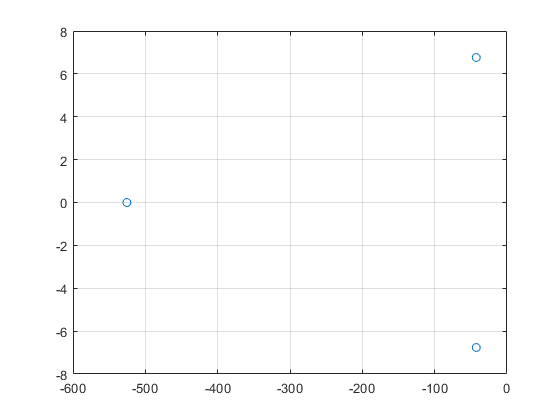

D_eig1_real=real(D_eig1);
D_eig1_ima=imag(D_eig1);

figure
scatter(D_eig1_real,D_eig1_ima/2/pi)
grid on
box on

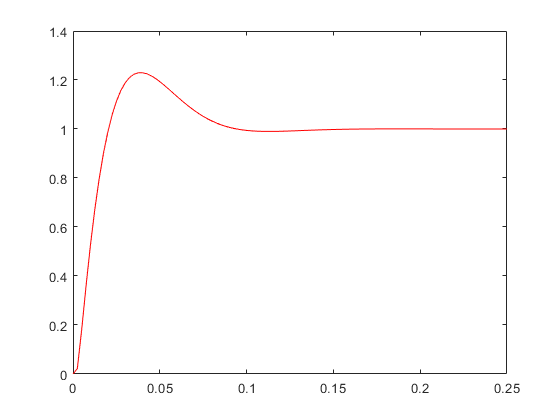


s = tf('s');
b = A(1,2);
c = A(1,3);
d = A(2,1);
e = A(2,2);
f = A(2,3);
h = A(3,2);
tf_test = 1/(s^3+s^2*-e+s*(f-b*d)+c*d*-h);
% figure;pzmap(tf_test);grid on;

AA=eye(3)*s-A;
tf1=inv(AA)*B;
figure
% plot(Il_sim.Time-0.2,Il_sim.Data,'-b')
% xlim([0 0.2])
% ylim([0 3])
% hold on
% plot(vc_sim.Time-3,vc_sim.Data,'-b')
% xlim([0 3])
% hold on
[y,tout]=step(tf1(2),0.25);
plot(tout,y,'-r')

% grid on
% hold on

## Compare to sim output

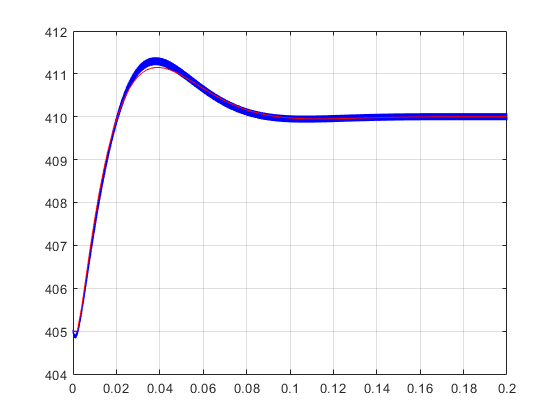

figure
plot(vc_sim.Time-1,vc_sim.Data,'-b')
xlim([0 0.2])
hold on
[y,tout]=step(tf1(2),0.2);
plot(tout,y*5+Vc,'-r')
grid on
hold on